# Computing the cosine using Taylor series approximations

*Written by Zamfir Ștefan-Alexandru, 17 March 2022.*

This project aims to quantify the precision of my implementation of the cosine function.

All results will be compared against MATLAB's implementation, `cos(x)`.

## The taylorcos function

There are 4 important optimizations I discovered while working on the function:

- **The cosine is an even function**. All negative values of `x` can be converted to positive values using `abs(x)`.

- **The cosine is a periodic function**. We only need the result of `mod(x, pi * 2)` in our computations, also saving a huge amount of time and precision.

- The cosine in `[0, pi * 2)` is **composed as an y-reflection** of the cosine in `[0, pi)` and `[pi, pi * 2)`. If `x > pi`, then we can subtitute it with `pi * 2 - x`.

- The cosine in `[0, pi)` is **composed as a x-reflection** of the cosine in `[0, pi / 2)` and `[pi / 2, pi)`. if `x > pi / 2`, then we can subtitute it with `pi - x` **and multiply the end result by -1**.

- If, after applying the previous steps, the `x` is in `[pi / 4, pi / 2]`, then we reduce it further by computing the sine. The appropiate formula is `cos(x) = sin(pi / 2 - x)`. We use the Taylor series for the sine instead of cosine in order to compute the sine.

The reason for reducing the range of `x` to `[0, pi / 4`] is simple. The more terms we compute in the Taylor series, the bigger the approximation range gets. What I mean by that is you can't compute the cosine of `10 * pi` if you only have the first three terms of the series. You need to bring more terms for that.

Well, because our range is so small, we will get **an accurate approximation within the first **`8 - 9`** terms**. If we were to not use the 5th step, the approximation would only get good after the 10th term.

### taylorcos.m

% Input is x and terms, these are example values
x = 123456.123456;
terms = 12;

% The cos function has a periodicity of 2 * pi
% Also, the cos function is an even function
x0 = abs(mod(x, 2 * pi));
coef = 1;

% First reflection
if x0 > pi
    x0 = 2 * pi - x0;
end

% Second reflection
if x0 > pi / 2
    coef = -1;
    x0 = pi - x0;
end

y = 0;
% Last optimization
if x0 > pi / 4
    x0 = pi / 2 - x0;

    % Sine
    for i = 0:terms
        y = y + (-1) ^ i * x0 ^ (2 * i + 1) / factorial(2 * i + 1);
    end
else
    % Cosine
    for i = 0:terms
        y = y + (-1) ^ i * x0 ^ (2 * i) / factorial(2 * i);
    end
end

% In case we reflected the second time
y = coef * y;

fprintf("taylorcos(x) using %g terms (above) and cos(x) (below)\n%.16d\n%.16d\n", ...
    terms, y, cos(x));

taylorcos(x) using 12 terms (above) and cos(x) (below)
-5.7601758031359596e-01
-5.7601758031752992e-01


fprintf("Their difference is:\n%.4d", abs(y - cos(x)));

Their difference is:
3.9340e-12

## How the method compares to MATLAB's by number of Taylor terms

Let us plot the difference between the two methods:

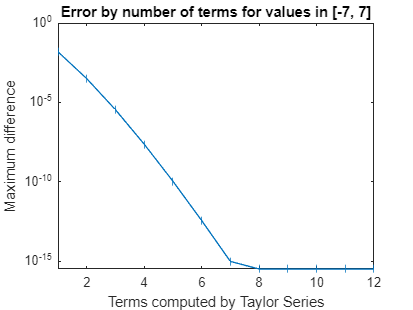

terms = 1;
maxterm = 12; % The amount of terms computed by the Taylor series
maxdiffs = zeros(1, maxterm);

x = -7:.02:7; % Range of computation

% Iterate through the number of terms to be used by series
while terms < maxterm + 1
    outputs = zeros(1, 10/.02); % Output of taylorcos
    tests = zeros(1, 10/.02); % Output of cos
    diff = zeros(1, 10/.02); % Their difference

    counter = 1;
    for i = x
        outputs(counter) = taylorcos(i, terms);
        tests(counter) = cos(i);
        diff(counter) = outputs(counter) - tests(counter);
    
        counter = counter + 1;
    end
    
    maxdiffs(terms) = max(abs(diff));
    terms = terms + 1;
end

% Plot the error by number of terms
plot(1:maxterm, maxdiffs, "-|");
title('Error by number of terms for values in [-7, 7]')
xlabel('Terms computed by Taylor Series')
ylabel('Maximum difference')
set(gca, 'YScale', 'log')
xlim([1 maxterm])

Interestingly, for the 10th, 11th and the 12th terms, the difference is exactly the same (`3.33e-16)`. I suspect there simply isn't room for `double` to quantify numbers less than `3.33e-16`.

## Limitations

The difference starts to broaden as the value of `x` increases since we are computing `mod(x, pi * 2)`. This happens because representable floating point numbers start getting sparser and sparser as their magnitute increases. If `x > 10^17`, the modulo function starts to fail.

in = 10^17;
epsilon = eps(in);
fprintf("The difference between %d and the next represented double is %d", in, epsilon);

The difference between 100000000000000000 and the next represented double is 16

**A difference of **`16`**. **You really can't provide the modulo of `6.38` if your numbers are `16` units apart.

The solution is to accurately compute the modulo. If that is done correctly, then the Taylor approximations are guaranteed to give you a difference no more than `3.33e-16` from MATLAB's implementation. For your information, `eps(pi / 4) = 1.11e-16`. The function is really close to MATLAB's.

There exists a way of doing that by providing enough bits of `pi`. An implementation that's used by MATLAB can be found [here](https://github.com/bminor/newlib/blob/master/newlib/libm/math/k_rem_pio2.c).